# Chance, Machine Learning Algorithms, MVPA, Brains on Trial

Commentary on this assignment:

This assignment revisits concepts from probability and hypothesis testing in assessing accuracy of machine learning algorithms. Then you’ll investigate a specific ML algorithm (separate submission). Then you’ll apply machine learning to a more complex problem than the 4 brain regions, which will allow you to apply methods to avoid overfitting. Finally, you’ll read or watch a video about the use of neuroscience in the courtroom and in lie detection, which raises important questions about how our legal system works. 

I provided very rough time estimates just to give you a sense of scale. I expect that there will be lots of variability in how much time people spend on this assignment overall and how much time people spend in each section. I trust you to make the good decisions for your learning goals and the course goals around challenging yourself, engaging your curiosity, and contributing to class. 

This document is a bit long, so I’ve included a linked table of contents and pictures of puppies (puppies only available in this version: [https://docs.google.com/document/d/1CmVUOSBBxdDdp-JU8pCzN5pKm6gdCE1sWJtiQXHqv4E/edit?usp=sharing)](https://docs.google.com/document/d/1CmVUOSBBxdDdp-JU8pCzN5pKm6gdCE1sWJtiQXHqv4E/edit?usp=sharing)).

The data you need are here: [https://drive.google.com/file/d/12cJmNYllwkhTGyHa9NAWpZWJVqPw4hib/view?usp=sharing](https://drive.google.com/file/d/12cJmNYllwkhTGyHa9NAWpZWJVqPw4hib/view?usp=sharing) 

[](https://docs.google.com/document/d/1CmVUOSBBxdDdp-JU8pCzN5pKm6gdCE1sWJtiQXHqv4E/edit#heading=h.w3ft5ksh9mr)

# Understanding “chance” in relation to classification [30 mins]

In this section, we’re going to explore probability in relation to classification accuracy. We’ll use the example from our faces vs houses fMRI data. In the training data, we have 162 total examples and in the test data we have 54 total rows of data. Each is evenly split between faces and houses. 

If my algorithm just flips a coin each time (“operates at chance level”, p(face)=0.5): 

## Exercise 1a: What is the most probable accuracy?

I think it should be close to 50, but since we have a discrete sample set, the accuracy might not be exactly 50 if there is an odd number of samples

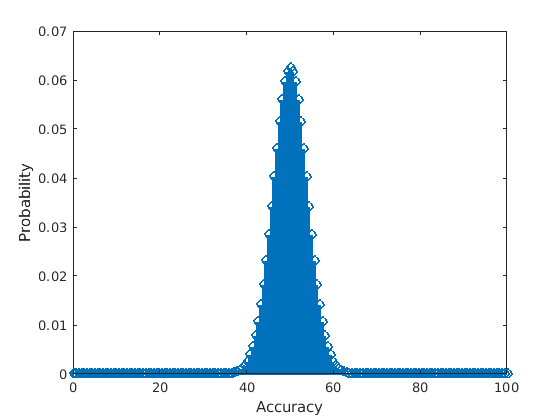

n = 162;
test_n = 54;
b = makedist("Binomial", 'N', n, 'p', 0.5);
x = 0:n; % number of correct predictions
stem(100.*(x./n), b.pdf(x), 'LineWidth', 2);
xlabel('Accuracy');
ylabel('Probability');

## Exercise 1b: What is the expected value of the accuracy?

Here are some resources about expected values that might be helpful:

[https://ocw.mit.edu/courses/mathematics/18-05-introduction-to-probability-and-statistics-spring-2014/readings/MIT18_05S14_Reading4b.pdf](https://ocw.mit.edu/courses/mathematics/18-05-introduction-to-probability-and-statistics-spring-2014/readings/MIT18_05S14_Reading4b.pdf)

[https://www.stat.purdue.edu/~zhanghao/STAT511/handout/Stt511%20Sec3.3.pdf](https://www.stat.purdue.edu/~zhanghao/STAT511/handout/Stt511%20Sec3.3.pdf) 

Expecting around 50, but it can be a non-discrete integer because it is a weighted average

expectedValueAccuracy = b.mean/n

expectedValueAccuracy = 0.5000

## Exercise 2a: For the training data, what is the probability of getting an accuracy of 50% or worse?

p = binocdf(n*0.5, n, 0.5) % inclusive of 50%

p = 0.5313

## Exercise 2b: For the training data, what is the probability of getting an accuracy of 50% or worse?

% for testing data
p = binocdf(test_n*0.5, test_n, 0.5) % inclusive of 50% and fewer options so each option has more, so greater cumulative sum

p = 0.5540

I want to set a threshold to reject the hypothesis that my algorithm is operating a chance level. Let’s say that I feel comfortable being wrong 10% of the time when my algorithm is operating at chance. 

## Exercise 3a: What should I choose as my accuracy threshold for the training data? 

 null_hypothesis: my algorithm is operating at chance level

alternative_hypothesis: my algorithm is not operating at chance level

alpha = 0.1

b = makedist("Binomial", 'N', n, 'p', 0.5);
100 * icdf(b, 0.9)/n % if 90% were correct, find number correct

ans = 54.9383

## Exercise 3b: What accuracy threshold should I use for my test data?

b = makedist("Binomial", 'N', test_n, 'p', 0.5);
100 * icdf(b, 0.9)/test_n % if 90% were correct, find number correct

ans = 59.2593

## Exercise 3c: Are these the same or different? Why?

Different because there are a different number of trials in train and test. If there are more trials, we can be more confident in our result and tighten the range.

Now, let’s suppose I have an algorithm that is 70% accurate in reality. 

## Exercise 4: What is the probability that it will perform at chance or worse on the test data?

p = 0.7;
binocdf(0.5*test_n, test_n, p)

ans = 0.0016

In the questions above, we have been considering a situation where we have an equal number of face and house examples in our data. Now let’s think about a situation where that is not the case. Our training data still has 162 total examples, but now 130 of them are faces.

## Exercise 5: What classification accuracy would we get on the train data if our algorithm just guessed face every time?

100 * 130/162

ans = 80.2469

## Challenge exercise: If our algorithm is still just a coin flipper, what is the expected value of the accuracy on our training data?

p = 0.5;
tp = 130 * p; % number of tp guessed correctly by random chance
tn = (162 - 130) * p; % number of tn guessed correctly by random chance
(tp + tn)./162

ans = 0.5000

Used a bayesian tree to draw prior and posterior

  .3 /              \ .7

.5 / \ .5     .5 / \ .5

# Use external resources to investigate, understand, and explain an algorithm [90 mins]

## Exercise 6: Explain algorithm (separate submission)

Choose one machine learning algorithm that you want to learn more about. Create a short explanation of this algorithm using whatever media you prefer (text, video, slides, whiteboard, audio, stone carving). 

Please share any good resources that you find in this mutual document. 

[https://docs.google.com/document/d/1AC4ULXd8sHEbw2M3u-tdkT0lvJylNvOjN7ojFg1NOQw/edit?usp=sharing](https://docs.google.com/document/d/1AC4ULXd8sHEbw2M3u-tdkT0lvJylNvOjN7ojFg1NOQw/edit?usp=sharing)

If you are new to machine learning, I recommend “K nearest neighbors” or “linear support vector machines” as good starting algorithms.

**How to submit this part:** This part of the assignment has a separate submission. This will serve as one of our learning check-offs. Please submit this on time if possible, since we’ll probably be doing a peer review between Monday and Wednesday.

# Multi-voxel pattern analysis on fMRI data [90 mins]

This is the fMRI data from one person (subject 2 in this study: [Haxby, J.V., Gobbini, M.I., Furey, M.L., Ishai, A., Schouten, J.L., Pietrini, P. (2001). Distributed and overlapping representations of faces and objects in ventral temporal cortex. Science, 293(5539):2425-30)](https://drive.google.com/file/d/13beA192gv2cO1j-2w3LxmeHQf5HmKhon/view?usp=sharing). There are 162 examples in the training set (these correspond to times where a person saw a house or a face). The labels tell you whether they were looking at a face or a house (same as last assignment). The data are linked at the top of this document.

Think of the voxel values as the potential features. In the train_fmri3d data, the voxels are in a 3 dimensional array (that is 40 x 64 x 64), plus a 4th dimension that is the 162 examples. However, for the classifier, you need to reshape the data to a 2 dimensional array. 

fmri2d= squeeze(reshape(train_fmri3d,1,1,[],162))'

fmri2d = 162×163840 single matrix
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0   

fmri2d has the dimensions of examples x voxels. However, we know that a bunch of these values are outside of the brain (since train_fmri3d is just a cube shape, and fun fact… our brains are not cube shaped). 

If we wanted to make a variable that contained every voxel in the brain (but excluded those not in the brain), we can use our brain mask. The brain mask has 1s for voxels in the brain and 0s for voxels not in the brain. We need to reshape this to align with the shape of fmri2d.

brainmask2d=single(reshape(mask,1,[]))

brainmask2d = 1×163840 single row vector
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Create a variable called brainvals that has the dimensions of (examples x voxels in the brain). Exercise 7: What are the actual dimensions of this variable (numbers)?

brainvals = fmri2d.*repmat(brainmask2d, [162 1])

brainvals = 162×163840 single matrix
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0

brainvals = brainvals( :, any(brainvals))

brainvals = 162×39912 single matrix
   45.1284  -26.6410  -42.3341  -15.2561   59.0485  -11.6695  -17.1604  -20.3824  -77.1514  -23.8082   17.2949   -5.3078    2.5875  -77.9387  -51.5206 -112.3978 -118.5641 -154.7213   38.1829   29.8786   26.7144  -20.8475  -61.6689 -131.9853  -27.1496   38.9386   24.6026  137.6996  158.2828   83.4007   58.0501   71.3809   66.7318   -1.3883   31.7280   18.6630   37.1858   88.9019   68.6382  -11.9085  -38.9541  -28.1824   65.7534   76.4503   48.2357   31.5696   60.9036  -64.0897  -70.4391  -25.4004
   41.1242  -16.6047  -36.3399   -8.2558   63.0427  -18.6882  -23.0782   -6.3803  -74.1712  -12.8589   31.2458  -12.3374    5.6373  -81.8823  -49.5271 -114.3968 -113.5586 -157.7485   27.1064   31.9451    7.7946  -12.8292  -60.6704 -119.0023  -22.2289   39.9617   20.6176  114.7681  162.3140   85.4038   65.0113   80.3467   62.7381  -11.3491   33.6662   15.6528   19.2132   86.8863   66.6836    0.0700  -50.9237  -34.1612   50.7714   78.4755   52.2763   33.5620   

162 x 39912

Dang, that’s a lot of voxels!  We could throw all of these voxels into our classifier, with each voxel serving as a feature. I would strongly recommend against this, why?

Think. Then highlight text below for answer

This may lead to overfitting our classifier. We have 162 examples and more than 30k variables.

Also, this will take forever to run and load.

## Exercise (BIG ONE): Run multivoxel pattern analysis (machine learning on voxels).

Run classification of faces vs houses using some subset of voxels. Be sure to use cross-validation to help prevent overfitting. 

For this part of the assignment, I’m asking you to piece together and extend some of the code that you’ve seen already. You can look at the brainViewer.mlx for more example code for selecting a subset of voxels from the data. You can look at fmriToFeaturesClassification for tips on how to implement the classifier using only code (though you’ll still need to look up how to do cross validation). You are also welcome to use the classificationLearner app if you prefer. 

You should explore different aspects of the feature space and document what you try and what you observed. Some things you might try:

- downsample the brain data to a smaller number of voxels randomly

- downsample the brain data to a smaller number of voxels by strategically selecting a brain region (you may still want to downsample within a region if it is big)

- use a dimensionality reduction technique such as PCA or ICA

- create new features that represent and summarize information about groups of voxels (this is like what we did by taking the average activity in each of the 4 regions, but you can get more creative if you want to)

Challenge: Choose some parameter to manipulate (e.g., # of nearest neighbors in KNN algorithm, or how many voxels to include). Generate a plot to represent the relationship between this parameter and a measure of how well your classifier performs (e.g., accuracy). Important tips (feel free to add some here or ask questions)

- As I mentioned in class, the ventral temporal lobe plays an important role in visual processing. One of the 4 regions that we explored before is the ventral temporal lobe.

- If you are using the Classification Learner, only use a table that has a reduced number of features already, otherwise, it will take forever to load the data. (My computer took several minutes to load a table that was 162 x 39913). For computational reasons, you’ll probably want max out at around 1000 (but this depends on your computer.)

- Matlab is probably looking for your “predictors” (features) to be in a table. If you need to convert an array to a table, check out: array2table(brainvals).

- If you are using Matlab 2019, you’ll need to take one additional step if you want to use the classificationLearner app. You must put the “responses” and the “predictors” in the same table. 

- You can do this by following this general format: train_all = [table(train_labels) train_4regions ]; In your version, you’ll have a different variable than train_4regions.

- Or you can use something like this if you have an array: 

- train_table2d = array2table(train_fmri2d); %

- train_table2d.labels = train_labels;

- Other tips from students (you can add a comment here).

n = 162;
region1 = fmri2d.*repmat(single(reshape(mask_region1,1,[])), [n 1]);
region1 = region1( :, any(region1))

region1 = 162×334 single matrix
   44.8421   29.0900   88.2853  -23.1248   -0.8906    4.6762   25.0965   -6.1110   -9.8206  -34.2827   -3.5229   -7.4850   24.8742  -29.5392 -124.1139  -48.3919   21.4351  -33.6712  -47.1674  -23.7241   -4.5264  -27.1810  -38.5469   62.3972  -19.3586  -13.4700   -6.9028    2.6887   31.0104  -12.7237  -18.9205    7.8046   13.4944   75.5431  -68.2044  -35.3210  -50.2615  -29.2665  -13.3425  -13.9733   -6.8752  -40.5720   -9.2395  107.6748   50.6947   27.9277   -3.2052   42.2067  -15.9438  -19.5484
   40.9222   27.1457  106.1361  -10.0830    7.1035    4.7111   23.0804    0.8875   -0.8534  -29.2738    2.4674   -3.4774   20.8742  -11.7150 -113.1031  -46.3841   20.4355  -33.6868  -42.1799  -22.7375   -5.5060  -18.2302  -37.5695   71.3558   -8.3970  -11.4936   -3.9174   -0.2952   27.0321  -13.7488  -19.8869   12.7579   12.5575   87.5089  -55.2923  -27.3378  -46.2824  -34.2885  -14.3439   -8.9508    2.0865  -37.5485   -7.2222  120.6520   54.7052   32.8400   -0.1

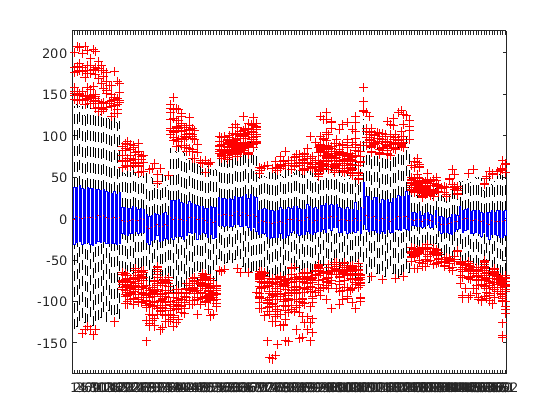

% boxplot by sample
boxplot(region1')

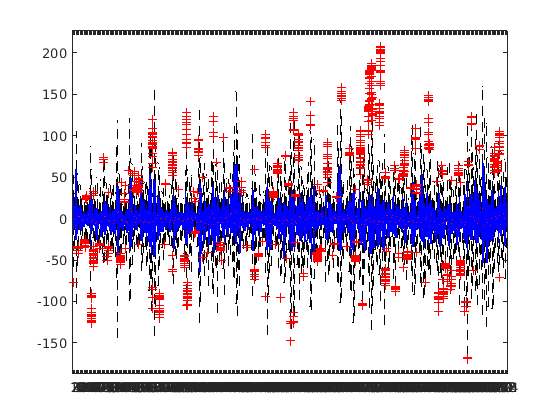

% boxplot by feature
boxplot(region1)

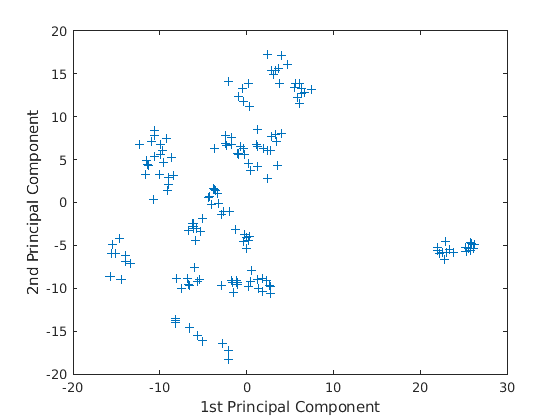

%corr(region1,region1);
[wcoeff,score,latent,~,explained] = pca(region1,'VariableWeights','variance');
figure()
plot(score(:,1),score(:,2),'+')
xlabel('1st Principal Component')
ylabel('2nd Principal Component')

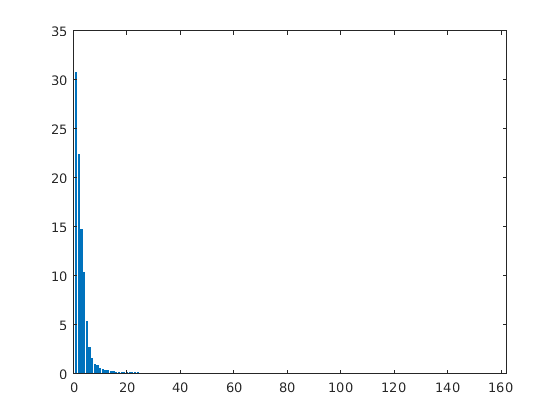

figure()
bar(explained)

region1 = fmri2d.*repmat(single(reshape(mask_region1,1,[])), [n 1]);
region1 = region1( :, any(region1));
region2 = fmri2d.*repmat(single(reshape(mask_region2,1,[])), [n 1]);
region2 = region2( :, any(region2));
region3 = fmri2d.*repmat(single(reshape(mask_region3,1,[])), [n 1]);
region3 = region3( :, any(region3));
region4 = fmri2d.*repmat(single(reshape(mask_region4,1,[])), [n 1]);
region4 = region4( :, any(region4));

[wcoeff1,score1,latent1,~,explained1] = pca(region1);
[wcoeff2,score2,latent2,~,explained2] = pca(region2);

[wcoeff3,score3,latent3,~,explained3] = pca(region3);
[wcoeff4,score4,latent4,~,explained4] = pca(region4);

explained1 % first 7

explained1 = 161×1 single column vector
   36.2376
   23.9686
   15.8495
   10.7287
    4.2774
    1.8731
    1.1529
    0.7581
    0.5554
    0.4024


explained2 % first 8

explained2 = 161×1 single column vector
   43.1001
   19.9416
    9.8243
    7.8444
    3.7835
    2.1081
    1.6599
    1.2185
    0.7526
    0.5982


explained3 % first 9

explained3 = 161×1 single column vector
   30.9446
   19.2588
   14.2063
    5.7947
    4.4339
    3.8011
    2.8119
    1.3967
    1.0155
    0.9470


explained4 % first 8

explained4 = 31×1 single column vector
   52.1313
   15.8923
   10.1483
    7.3441
    3.6160
    2.2814
    1.6386
    1.3586
    0.9103
    0.7898


region1_10 = score1(:, 1:10)

region1_10 = 162×10 single matrix
  882.2699 -249.0720  -17.4099   99.1775   28.8254  -62.8130  -19.3104   36.6531   35.1150  -14.9584
  870.9958 -238.3671    0.1133  148.2624   38.4298  -62.0343  -25.2092   43.2560   63.8712   19.5032
  884.9216 -229.5898   22.2092  141.0955   41.0693  -65.1118  -37.8074   31.4339   60.3092   15.7281
  873.9255 -247.0448  -16.7304  142.4166   22.6208  -67.9866  -21.6513   26.2031   29.4132    0.9268
  855.6765 -251.0692  -18.9221  132.2741   39.1652  -76.4831  -13.2179   27.8672   31.5496    0.9355
  876.3199 -230.3638    3.4694  128.8664   34.3494  -67.4803  -25.3893   27.2125   36.7911    2.6659
  866.0078 -256.0186    6.7014  100.1808   11.7942  -53.0865  -13.0122   30.2270   24.7139  -13.1754
  877.5620 -243.5495  -17.7944  103.2499   27.9399  -76.0061  -16.4831   19.0183   12.1393  -13.4048
  857.6501 -264.7130  -24.1600  118.0704   13.0859  -61.9725  -11.5007   23.3495   20.7249  -10.7477
  809.6169 -261.3054   67.0503   88.7841   25.6060  -41.0

region2_10 = score2(:, 1:10)

region2_10 = 162×10 single matrix
  500.3787  -17.8039   53.0067  -63.0664   -6.9085  -30.1563   36.5739  -11.0019  -15.6458    6.3620
  476.8148  -18.8309   38.2953  -64.6518  -12.3547   -7.2812   24.9917    1.2449   -3.3462    6.4010
  474.8785  -14.6288   43.4600  -61.0633  -21.0159  -10.7514   29.6061   -0.8047   -3.9078   13.8884
  491.4526  -25.5925   48.6052  -56.0446  -13.0624   -5.6371   27.1252   -6.8921   -1.6591   11.7441
  474.1767  -13.9762   48.3750  -63.4748  -13.0364   -5.8352   31.7320    7.9991   -5.9890   11.2144
  487.9001  -23.4758   43.8801  -59.3961  -15.3894  -26.1054   30.9382  -18.9955   -0.2729   11.6652
  490.4452  -26.3618   42.5140  -63.7428    3.0023  -41.1618   27.9324  -19.6379   -0.2765   11.4706
  486.4983  -28.6231   48.3556  -61.0351    3.5750  -55.3451   30.2215  -16.7835   10.0168    1.2746
  504.4672  -30.7581   48.3434  -55.0466   -9.9613  -31.1667   20.1318  -13.8631   11.8187   -1.3392
  440.9283  -11.7494   18.2610  -34.5127   16.9274  -35.4

region3_10 = score3(:, 1:10)

region3_10 = 162×10 single matrix
 -602.9750    4.3032 -267.0129   -3.7728  -27.3058  -29.2039   46.4935   51.0825  -20.8520   65.4810
 -606.9026   16.3646 -247.8228   39.7788  -34.4314  -10.7661   16.0021    4.3593  -34.8852   88.2763
 -597.9197   -5.4570 -248.6415   19.6119  -34.7483  -12.5068   44.4269   22.7052   -4.3754   59.7175
 -600.8988  -15.2894 -242.4704    3.1686  -50.0556  -32.8292   36.7889   22.3156   -8.9473   75.0033
 -610.7221    8.3663 -244.7362   10.9536  -52.8146  -28.6015   41.1013    8.9603  -36.3337   71.7286
 -605.3700  -13.4790 -243.7588   11.9757  -54.5816  -40.2087   64.9597    3.9702   -5.7810   60.5054
 -569.9920    2.7016 -245.7481    5.8671  -11.7410  -29.9437   26.8847   18.8572   16.9785   44.1216
 -587.5948   -5.5146 -248.1978   27.1901  -25.3469  -60.6531   52.7184  -30.1970   20.2712   46.5481
 -583.7650  -48.5553 -213.8648   24.3634  -29.9500  -65.3586   76.7826   -1.7185   49.3799   25.2460
 -477.6545  -20.4015 -156.0078   -1.0636   58.3452  -51.4

region4_10 = score4(:, 1:10)

region4_10 = 162×10 single matrix
 -200.7725  -88.9944   66.3656   30.2970    7.5523    2.0962   -5.4538   -5.7794   30.9506  -18.6740
 -142.5894  -25.5757  128.2361   46.4931   -6.5584  -10.7303  -28.3200    9.1455   17.3167   12.5312
 -169.1275  -21.1523  101.0748   87.2609  -56.4232   12.0617    2.9201    9.8378    1.2357   15.9864
 -190.8640  -79.1459   77.3002   28.7072   -4.2127   -0.5531    6.3055   -0.1726   37.5303   -6.7976
 -185.5584  -79.0591   91.0915   35.9461   -4.6241   -1.3296    8.1930   -6.1525   38.9447   -6.4676
 -185.4122  -76.7435   78.5448   24.6691   -6.5634    6.8628   -1.1384   -0.2712   31.1081  -17.5585
 -197.2589  -59.4490   74.7602   43.4277   -8.1264   -1.1025  -22.3357    6.4737    9.5122    1.9462
 -207.4717  -75.2307   78.9758   28.4065  -20.0961   -1.3167    1.7366  -11.4634   29.6739    2.2047
 -212.6579  -75.7360   71.7959   24.7281   -7.0967   -1.8303   10.4450   -1.5655   30.9387    5.8777
 -230.9032  -86.6549   53.2212   31.3413   -8.3701    1.6

chosen_features = [region1_10 region2_10 region3_10 region4_10]

chosen_features = 162×40 single matrix
  882.2699 -249.0720  -17.4099   99.1775   28.8254  -62.8130  -19.3104   36.6531   35.1150  -14.9584  500.3787  -17.8039   53.0067  -63.0664   -6.9085  -30.1563   36.5739  -11.0019  -15.6458    6.3620 -602.9750    4.3032 -267.0129   -3.7728  -27.3058  -29.2039   46.4935   51.0825  -20.8520   65.4810 -200.7725  -88.9944   66.3656   30.2970    7.5523    2.0962   -5.4538   -5.7794   30.9506  -18.6740
  870.9958 -238.3671    0.1133  148.2624   38.4298  -62.0343  -25.2092   43.2560   63.8712   19.5032  476.8148  -18.8309   38.2953  -64.6518  -12.3547   -7.2812   24.9917    1.2449   -3.3462    6.4010 -606.9026   16.3646 -247.8228   39.7788  -34.4314  -10.7661   16.0021    4.3593  -34.8852   88.2763 -142.5894  -25.5757  128.2361   46.4931   -6.5584  -10.7303  -28.3200    9.1455   17.3167   12.5312
  884.9216 -229.5898   22.2092  141.0955   41.0693  -65.1118  -37.8074   31.4339   60.3092   15.7281  474.8785  -14.6288   43.4600  -61.0633  -21.0159  -10.751

covmat = cov(chosen_features)

covmat = 40×40 single matrix
	1.0e+05 *

    1.2204    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.5576   -0.1382    0.0200    0.0028    0.0031    0.0168    0.0056    0.0054   -0.0018    0.0032   -0.6255    0.2031   -0.2286   -0.0205   -0.0831   -0.0546   -0.0276    0.0228    0.0054    0.0097   -0.3138   -0.0736    0.0437    0.0163   -0.0061   -0.0104   -0.0112    0.0151    0.0131    0.0085
    0.0000    0.8072   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.1435   -0.3022   -0.0659    0.0231   -0.0083    0.0022    0.0022    0.0022   -0.0016   -0.0038    0.2817    0.4053   -0.0093   -0.0443   -0.1046    0.0290   -0.0107   -0.0080    0.0144   -0.0108    0.0361   -0.0181   -0.0746   -0.0638   -0.0192   -0.0005    0.0048    0.0297    0.0054    0.0030
    0.0000   -0.0000    0.5338   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0577    0.0592   -0.1738   -0.0265    0.0339   -0.0

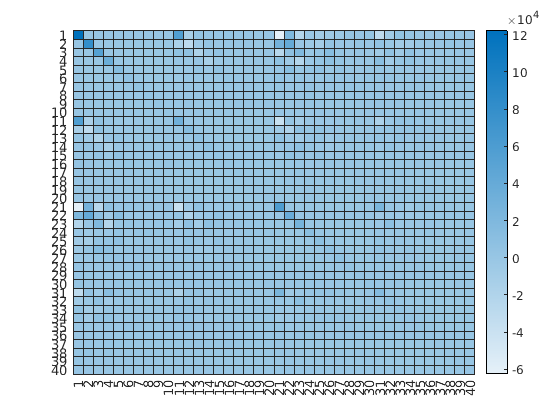

figure();
heatmap(covmat)

After doing PCA and choosing the top 10 features from each region (after the first 10 features the explained variance < 1), I got a reduced feature set of 40 features.

**Model                    Accuracy**

Fine Tree               88.9%

Medium Tree          88.9%

Coarse Tree           89.5%

Fine KNN               98.1% <-- pretty good training accuracy

Medium KNN          88.9%

# Brains on Trial [120 minutes]

Watch this video or read this paper and think about the prompts below.

- Brains on Trial 1 (60 minutes): [https://www.youtube.com/watch?v=o0eSqIAmKxU](https://www.youtube.com/watch?v=o0eSqIAmKxU)

- Neuroimaging and lie detection paper: [https://drive.google.com/open?id=1V9YiLcl82VtDBnQLG_0-LT87tdW2D5tM](https://drive.google.com/open?id=1V9YiLcl82VtDBnQLG_0-LT87tdW2D5tM)

Other suggested resources if you want more of this:

- Brains on Trial: Part 2: [https://www.youtube.com/watch?v=_cBK_fgTZvk](https://www.youtube.com/watch?v=_cBK_fgTZvk)

- Law, Responsibility, and the Brain paper: [https://drive.google.com/file/d/1P-AoQPkPbp2EjC6u9LD-IXqgPjoRrChR/view?usp=sharing](https://drive.google.com/file/d/1P-AoQPkPbp2EjC6u9LD-IXqgPjoRrChR/view?usp=sharing)

Prompt to start thinking about prior to class discussion:

How would you **go about determining** if a future, more accurate, version of brain-based lie detection technology should be permissible in the American justice system and in what situations? 

What information would you want? (How realistic is it to obtain this information?) What groups would you need to consider? What measurements of tool effectiveness would you want to see (and under what conditions)? What social and societal implications should you consider?

You should write notes on the video and the prompt. You can either submit them (I would enjoy reading them), or write a note that you did this (what an appropriately themed use of the honor code!).

**Gati's Notes**

- A jury is like a pooled decision maker

- I would want the data tested and fine-tuned to each individual

- **I would want all the jurors and judge to know the short-comings of the technology **(how do you make sure they listen and understand?)

- I would want masking techniques and adversarial patterns to be less effective